# MXB161 IW1 Introduction

This is your Individual Worksheet (IW).  Complete this worksheet at your own pace.  After you've completed the worksheet, you'll be ready to take the Quiz for this topic, which can be found on Canvas on the Topic 1 - Introduction page.

## Getting started

This worksheet is designed to be completed in conjunction with the associated online lecture on Canvas.

If you haven't yet started the online lecture, please start that first.  You'll be directed to return to this worksheet at the appropriate time in the lecture.

## 1.1 My First Spiral

Be sure you've watched the [Getting Started with MATLAB](https://au.mathworks.com/videos/getting-started-with-matlab-68985.html) video.  Notice how the presenter in that video at first interacted with MATLAB by entering code in the Command Window.  But shortly after that, she moved all her code into a Live Script, just like this file.

We'll be working in Live Scripts in MXB161.  They allow the blending of text, MATLAB code, web links, images, mathematical formulas, interactive controls, and more into a single file.

Within a Live Script, we can execute code, and the output appears in the Live Script.  Try this now: click Run Section 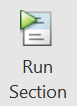 on the ribbon, or simply press Ctrl+Enter.

t = 0:0.1:1

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


You should see the output of the code `t = 0:0.1:1` appear directly below the command above.  Great!

The output shows that `t` is a *one-dimensional array*, often called a *vector*, which is simply a single row of numbers, rather like a single row of a spreadsheet.  In fact, to be more precise, we could call `t` a *row vector*, since it is indeed oriented as a row.

In these Live Script worksheets, you enter your MATLAB code into the grey Code boxes.  We provide you with plenty of Code boxes ready to go, but you can always add a new Code box anywhere you like by clicking the Code button .  Some Code boxes in the worksheet will be pre-filled to give you the idea, like the one in the previous section. Others will ask you to:

% Enter you answer here

and you are supposed to replace the green text with the required code.  Be sure to Run Section  (or Ctrl+Enter), to see the output of the code.  Alternatively, you can click Run and Advance  (or Ctrl+Shift+Enter) if you prefer to move on to the next section after you've run the code in the current section.  Try that now.

Now let's get on with our spiral.  We'll create another one-dimensional array (vector) called `x` whose elements have the values given by the formula $x = t \cos(4 \pi t)$.

x = t .* cos(4*pi*t)

x =          0    0.0309   -0.1618   -0.2427    0.1236    0.5000    0.1854   -0.5663   -0.6472    0.2781    1.0000


x =          0    0.0309   -0.1618   -0.2427    0.1236    0.5000    0.1854   -0.5663   -0.6472    0.2781    1.0000


Remember to run this code as explained above.

In this line of code, we multiply the array `t` by another array `cos(4*pi*t)` and assign the result to the new variable `x`. We can observe a few things:

- $\pi$ is spelled as `pi` in MATLAB

- When you multiply two arrays, you need to use `.*` rather than just `*`

- The variable x is created in the Workspace.  Confirm you now see `t` and `x` in your Workspace window.

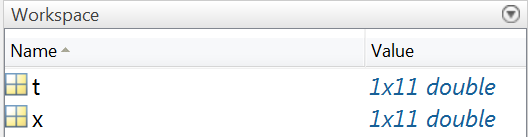

Now try the same code for calculating `x`, but without the dot:

x = t .* cos(4*pi*t)

y =          0    0.0951    0.1176   -0.1763   -0.3804   -0.0000    0.5706    0.4114   -0.4702   -0.8560   -0.0000


You should see a red error message from MATLAB, telling you there's an "Error using * " with advice on how you might fix it.

MATLAB's error messages are often quite helpful and informative. Be sure to read them carefully when you make an error so that you can correct it.  In this case, the error was that we used `*` instead of `.*` to do the multiplication.

Go back and fix the code, and confirm it now runs without an error.  It will just re-create the same array `x`, but this time without the error.

Now enter the command to create an array `y` whose elements have the values $y = t \sin(4 \pi t)$.

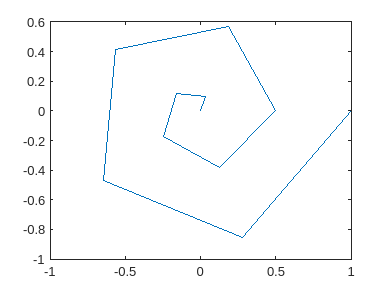

y = t .* sin(4 * pi * t)

Run your command, and you should get:

`y =`

`         0    0.0951    0.1176   -0.1763   -0.3804   -0.0000    0.5706    0.4114   -0.4702   -0.8560   -0.0000`

Now we can plot `x` and `y`.

plot(x, y)

If you got your command for `y` correct in the section above, this plot should produce a crude spiral.  If not, go back and see if you can fix up your command -- be sure to rerun it after you make any changes.

We can get a smoother plot by using more points. First, let's re-create the variable `t` to include more values between zero and one.

t = 0:0.01:1;

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Hmm...nothing seems to happen.  But, if you look in your Workspace window, you will see that indeed `t` is now of size 1x101

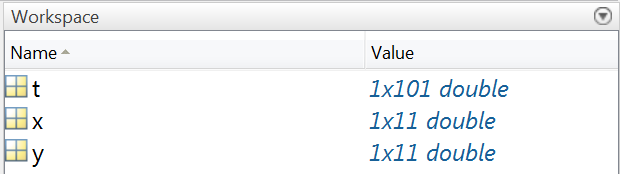

You can double click its name to confirm all the values are there.  The reason we didn't see the new output for `t` in the worksheet, is that we *terminated the line with a semicolon*.

To see the difference, try that same line again now without the semicolon.

t = 0:0.01:1

ans =      1   101


The output appears in the worksheet this time (albeit, truncated).  If you hover your mouse over the output, there is also little arrow at the end  you can click to open up the variable in the variable editor if you want to see it all.

As a rule of thumb: when you're working in a Live Script, it's usually best to keep the output visible (so, don't use a semicolon).  But somtimes you don't want to clutter your screen with the output of the code, so you can use the semicolon, remembering that the code will still *run* nevertheless.

To just check the size of `t` without printing all its values, you can use

size(t)

x =          0    0.0099    0.0194    0.0279    0.0351    0.0405    0.0437    0.0446    0.0429    0.0383    0.0309    0.0206    0.0075   -0.0082   -0.0262   -0.0464   -0.0681   -0.0911   -0.1147   -0.1385   -0.1618   -0.1840   -0.2046   -0.2228   -0.2381   -0.2500   -0.2579   -0.2615   -0.2603   -0.2541   -0.2427   -0.2260   -0.2040   -0.1768   -0.1448   -0.1082   -0.0675   -0.0232    0.0239    0.0731    0.1236    0.1746    0.2250    0.2741    0.3207    0.3641    0.4031    0.4370    0.4649    0.4861


You should see that the `ans`wer is 1  101 meaning `t` has 1 row and 101 columns.  MATLAB always calls the result of a calculation `ans` if you don't give it a name yourself, like just now.

Now we can recompute `x` and `y` using the same formulas as before.  Note that we've given you the answer for `y` here, so if you didn't get it right before, you can see now what it should have been.

x = t .* cos(4*pi*t)

y =          0    0.0013    0.0050    0.0110    0.0193    0.0294    0.0411    0.0539    0.0675    0.0814    0.0951    0.1081    0.1198    0.1297    0.1375    0.1427    0.1448    0.1435    0.1387    0.1301    0.1176    0.1012    0.0810    0.0572    0.0301    0.0000   -0.0326   -0.0671   -0.1031   -0.1397   -0.1763   -0.2122   -0.2466   -0.2786   -0.3076   -0.3329   -0.3536   -0.3693   -0.3793   -0.3831   -0.3804   -0.3710   -0.3546   -0.3313   -0.3012   -0.2645   -0.2216   -0.1730   -0.1194   -0.0614


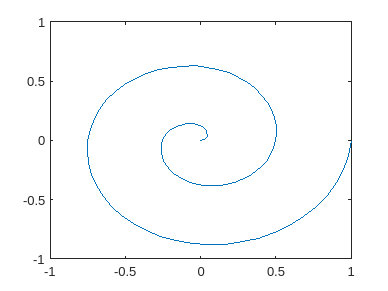

y = t .* sin(4*pi*t)

Now re-do the plot.

plot(x, y)

Let's give our figure some axis labels and a title.

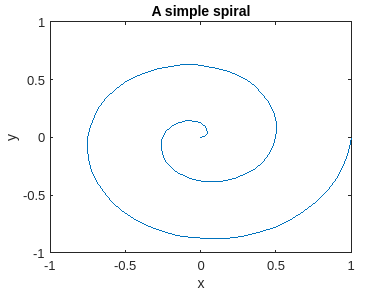

xlabel x
ylabel('y')

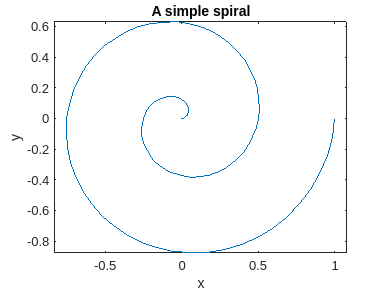

title("A simple spiral")

Notice there are three(!) different ways to pass a string of text to a function like `xlabel`, `ylabel`, or `title`.  We can simply type the string next to the function name with a space in-between, like `xlabel x`.  Or we can call the function using parenthesis, and pass the string by delimiting it with either single quotes or double quotes.  In any case, MATLAB colours the text purple so that it stands out. Check that your figure now has axis labels and a title.

Our spiral is also looking a bit out of shape. That's because MATLAB doesn't use equal spacing for the *x* and *y* axis by default. Let's change that now:

axis equal

n = 6

That's better.

Note that at any time you can click the arrow  on the top right of the figure (hover your mouse over the figure for a moment to make the buttons appear), to open it in a dedicated Figure window.  Try that now.  From that Figure window you can save the figure as a separate file (in various formats) to keep, or maybe share with your friends.

### Interactivity

Finally, we want to make our spiral figure interactive.  The user should be able to select a value of $n$ in the formulas


$$x = t\cos(n\pi t),\qquad y = t\sin(n\pi t)$$


rather than *hard-coding* the value $n = 4$ as we did above.

To insert a numeric slider so the user can choose the value of $n$, we need to insert a Control.  Click the  button and choose   Numeric Slider.

Edit the slider properties to range from Min = 1 to Max = 10, and Run the Current section on Value changing.

Add your plotting code directly below, changing the hard-coded value of 4 in the formulas, to the variable `n`.

Finally, to make it all work together, you need to assign `n = ` to the value of the slider, thereby setting the value of n that the user has selected.

n = 6

x =          0    0.0098    0.0186    0.0253    0.0292    0.0294    0.0255    0.0174    0.0050   -0.0113   -0.0309   -0.0530   -0.0765   -0.1002   -0.1227   -0.1427   -0.1587   -0.1697   -0.1743   -0.1719   -0.1618   -0.1438   -0.1179   -0.0847   -0.0450   -0.0000    0.0487    0.0994    0.1500    0.1985    0.2427    0.2805    0.3099    0.3293    0.3373    0.3329    0.3155    0.2851    0.2422    0.1879    0.1236    0.0514   -0.0264   -0.1069   -0.1873   -0.2645   -0.3353   -0.3968   -0.4463   -0.4813


x = t .* cos(n * pi * t)

y =          0    0.0019    0.0074    0.0161    0.0274    0.0405    0.0543    0.0678    0.0798    0.0893    0.0951    0.0964    0.0925    0.0829    0.0674    0.0464    0.0201   -0.0107   -0.0448   -0.0809   -0.1176   -0.1531   -0.1858   -0.2138   -0.2357   -0.2500   -0.2554   -0.2510   -0.2364   -0.2114   -0.1763   -0.1320   -0.0796   -0.0207    0.0426    0.1082    0.1734    0.2358    0.2928    0.3418    0.3804    0.4068    0.4192    0.4165    0.3981    0.3641    0.3149    0.2518    0.1767    0.0918


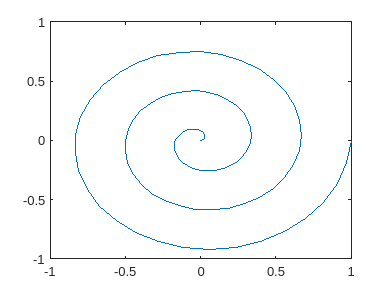

y = t .* sin(n * pi * t)

plot(x, y)

If you got it all right, you should have your interactive spiral figure!  If it's not working, you can refer back to the video to see what step you might have missed.

If you like, you can temporarily hide the code in the worksheet, by clicking the bottom of three buttons on the far right 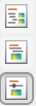, next to the vertical scrollbar, leaving just the slider.  You can get the code back by clicking the middle button (or if you prefer, the top button, which puts all the output off to the side, rather than inline).

**Well done on finishing this section**.  Now you can return to the online lecture.

## 1.2 More on plotting

Now run the commands

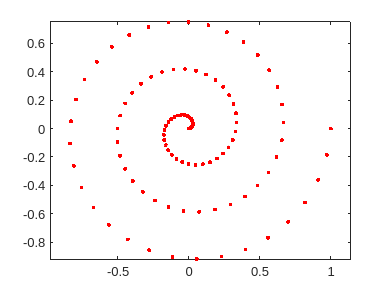

figure
plot(x, y, 'r.')
axis equal

You can see the spiral is now made up of red dots for each of the points, rather than blue lines connecting each of the points.

Notice how we used the `figure` command first, which ensures we start an entirely new figure, rather than modifying an earlier figure.

Previously we used `plot(x, y)` and MATLAB used blue lines in the plot. This is the default. If you want something else, like red dots, you include this as an option in the plot command. Many options are possible, by combining the colours, symbols and line types listed below:

`   b     blue          .     point              -     solid`

`   g     green         o     circle             :     dotted`

`   r     red           x     x-mark             -.    dashdot`

`   c     cyan          +     plus               --    dashed`

`   m     magenta       *     star`

`   y     yellow        s     square`

`   k     black         d     diamond`

`                       v     triangle (down)`

`                       ^     triangle (up)`

`                       <     triangle (left)`

`                       >     triangle (right)`

`                       p     pentagram`

`                       h     hexagram`

What do you think the code

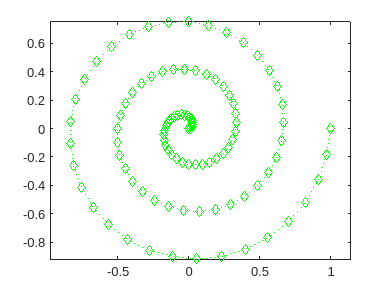

figure, plot(x, y, 'gd:'), axis equal

will produce? Try it to find out. Notice also how you're allowed to include multiple commands on a single line of code, provided they're separated by commas (semicolons would work too).

Write the command to plot the spiral with black stars connected by a dash-dotted line.

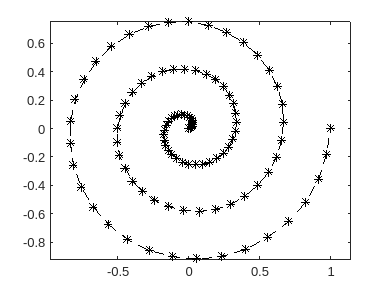

figure, plot(x, y, 'k*--'), axis equal

To include multiple plots on the same figure, you need to `hold on` to the figure after the first plot. For example, here we will create a figure with a "double spiral", by plotting our existing spiral *and* the rotated spiral


$$x = -t \cos(n\pi t), \ \ y = -t \sin(n \pi t)$$


together on the same figure.

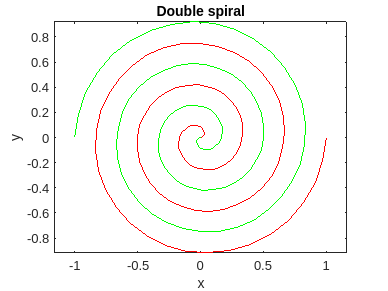

figure
plot(x, y, 'r')    % plot standard spiral
hold on            % hold the current figure
plot(-x, -y, 'g')  % plot rotated spiral (on the same figure)
axis equal
xlabel('x'), ylabel('y'), title('Double spiral')

Notice the green text beginning with percent signs in the lines of code above.

% plot standard spiral

These are known as *comments*. Any text beginning with a percent sign is ignored by MATLAB (other than by colouring it green), so can be used to comment (i.e. describe) your code for the benefit of human readers.  It's good practice to add comments to your code.

Now make the spiral plot interactive, by including a slider to choose the value of $n$.

**Well done on finishing this section**.  Now you can return to the online lecture.

## 1.3 Lissajous curves

The equations for a Lissajous curve are:


$$x = \sin(a\pi t),\quad y = \cos(b\pi t)$$


Actually the equations can be a little more general than this, but for our purposes let's stick with this definition. This time $t$ we will let the parameter $t$ range from $0$ to $2$. The values of $a$ and $b$ determine the character of the curve.

Your task for this section is to make an interactive Lissajous curve figure with two sliders: one for $a$ and one for $b$.

figure
t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


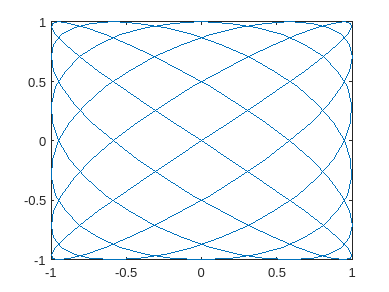

a = 6;
b = 5;
x = sin(a * pi * t);
y = cos(b * pi * t);
plot(x, y)

Once it's working, you should be able to replicate the same figures in the online lecture by adjusting $a$ and $b$.  Check that your figures agree!

**Well done on finishing this section**.  Now you can continue on to the exercises.

# Exercises

1. Plot the three-dimensional helix, given by the equations


$$x = \cos(8 \pi t)\\
y = \sin(8 \pi t)\\
z = t$$


for t between zero and one. The command you need is `plot3`.  You can look up the documentation for this command using the   feature in MATLAB, or just in a web browser, search for "plot3 matlab".  Get used to finding and learning about new MATLAB commands this way.  Being comfortable with discovering (or rediscovering) new commands is *much* more important than memorising a whole list of commands.

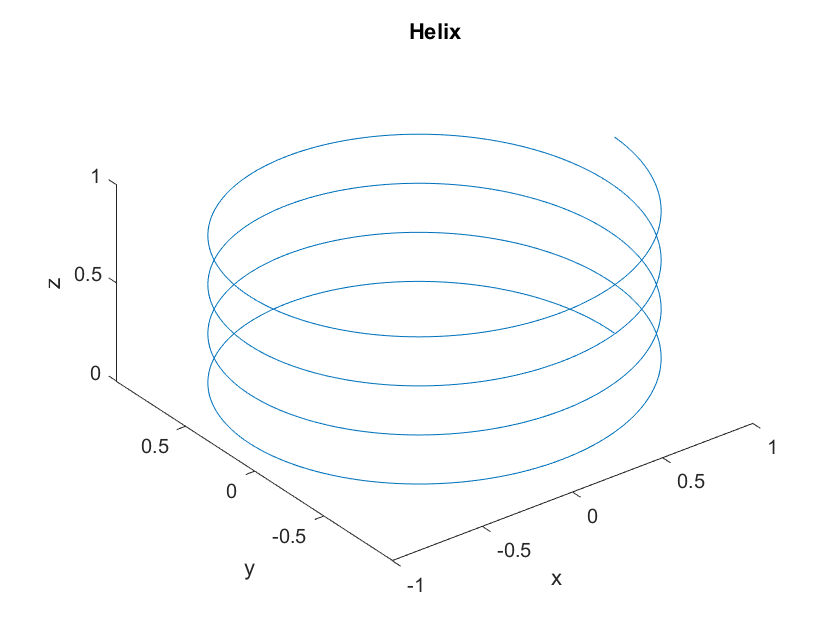

Enter the commands to produce a figure of a helix.

t = 0:0.01:1
x = cos(8 * pi * t)

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y = sin(8 * pi * t)

x =     1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686    1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686


y =          0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487


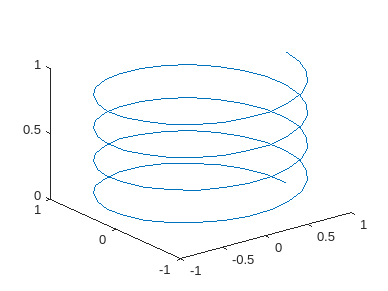

plot3(x, y, t)

2. Now plot a *double helix* consisting of the standard helix and a rotated helix.

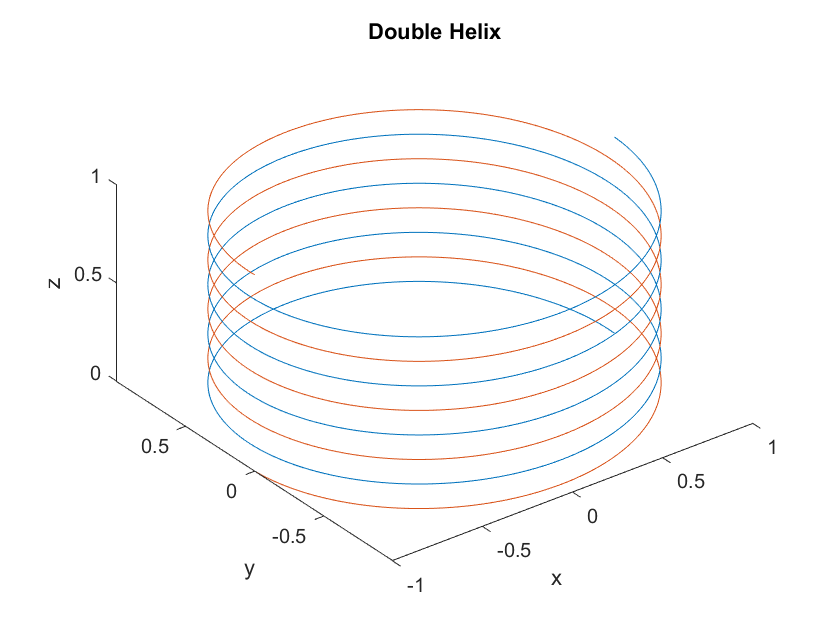

Enter the commands to produce a figure of a double helix.

figure
x = cos(8 * pi * t)
y = sin(8 * pi * t)

x =     1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686    1.0000    0.9686    0.8763    0.7290    0.5358    0.3090    0.0628   -0.1874   -0.4258   -0.6374   -0.8090   -0.9298   -0.9921   -0.9921   -0.9298   -0.8090   -0.6374   -0.4258   -0.1874    0.0628    0.3090    0.5358    0.7290    0.8763    0.9686


plot3(x, y, t)

y =          0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487


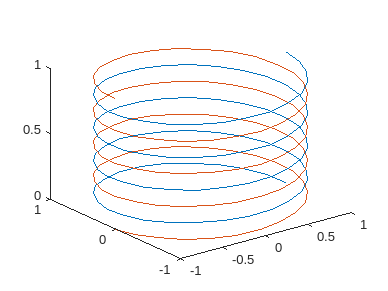

hold on
plot3(-x, -y, t)

3. How would you modify the equations for the helix to produce the following "corkscrew" curve?

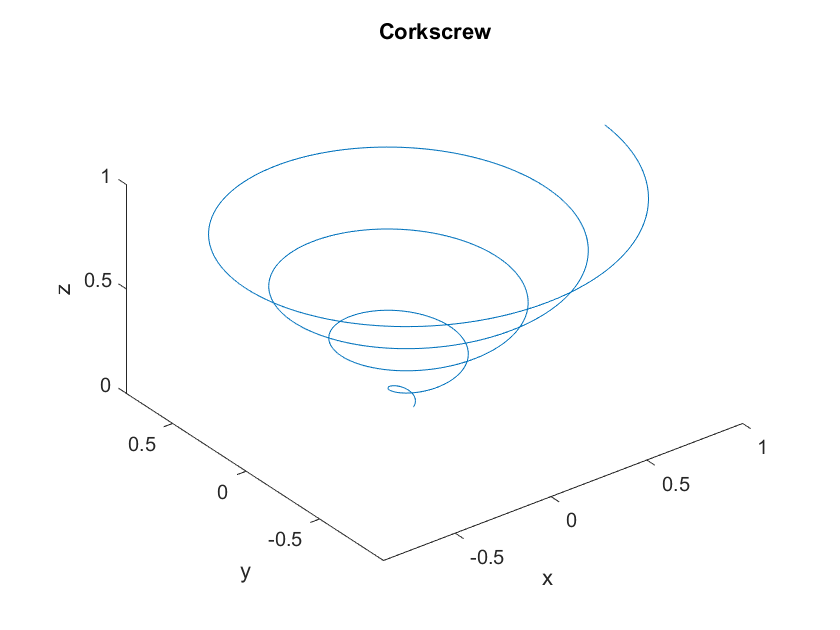

Enter the commands to produce a figure of a corkscrew.

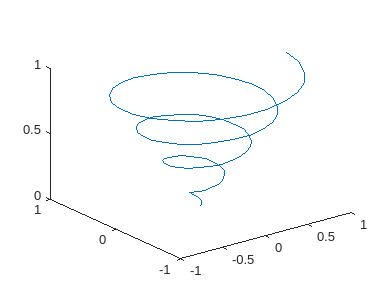

figure
plot3(x .* t, y .* t, t)

4. Now plot a *double* corkscrew!

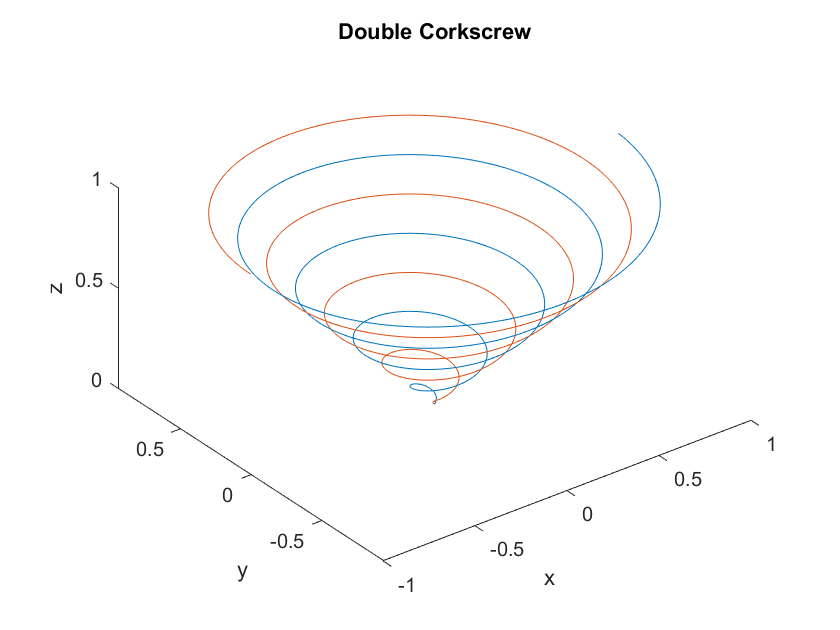

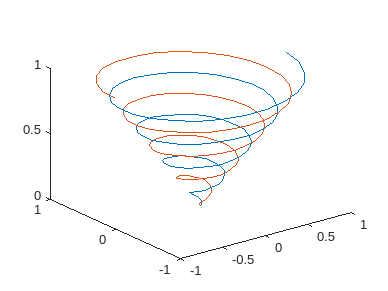

figure
plot3(x .* t, y .* t, t)
hold on
plot3(-x .* t, -y .* t, t)

# Quiz

The Quiz is your assessment for this topic.  The link can be found on Canvas on the Topic 1 - Introduction page.  Follow the link to complete the Quiz.